clear;

% Constants
c1 = 0.1;
c2 = 0.1;
W = 0.7;

% Independent Variables
NumOfAgents = 1000;
NumOfPatterns = 10;
NumOfGenerations = 10000;

%Dependent Variables
PatternSize = NumOfAgents/NumOfPatterns;
PatternX = zeros(PatternSize, NumOfPatterns);
PatternV = zeros(PatternSize, NumOfPatterns);
PatternM = zeros(PatternSize, NumOfPatterns);
CentrePixel = ceil(PatternSize/2);

for ag = 1:1:NumOfPatterns
    PatternX(:,ag) = ElectricField(rand(PatternSize,1));
end

F = zeros(NumOfPatterns,1);

tic
T = TransmissionMatrix(PatternSize, 0.5);
toc

Elapsed time is 0.110552 seconds.



tic
OldT = OldTransmissionMatrix(PatternSize);
toc

Elapsed time is 0.004657 seconds.



for i = 1:1:NumOfPatterns
    F(i) = FindFitness(PatternX(:,i),T,CentrePixel);
end

PatternPB = F;
TeamPB = max(PatternPB);

PatternPBLog = zeros(NumOfGenerations,NumOfPatterns);
TeamPBLog = zeros(NumOfGenerations,1);
PatternPBLog(1,:) = PatternPB;
TeamPBLog(1) = TeamPB;


PatternXLog = zeros(PatternSize, NumOfPatterns, NumOfGenerations);
PatternXLog(:,:,1) = PatternX;
tic
for gen = 2:1:NumOfGenerations
    
    for pat = 1:NumOfPatterns
        PatternV(:, pat) = c1*rand*(PatternPB(pat) - PatternX(:, pat)) + c2*rand*(TeamPB - PatternX(:, pat));
        PatternM(:, pat) = W*PatternV(:, pat);
        PatternX(:, pat) = PatternX(:, pat) + PatternV(:, pat) + PatternM(:, pat);
    end
    % Note: Old for loop code is commented at the bottom of this document
    
    %PatternX = sigmoid(PatternX + PatternV + PatternM);

    A = T * PatternX;
    I = abs(A).^2;
    F = I(CentrePixel, :);
    for pat = 1:1:NumOfPatterns
        if F(pat) > PatternPB(pat)
            PatternPB(pat) = F(pat);
        end
    end
    if max(PatternPB) > TeamPB
        TeamPB = max(PatternPB);
    end
    PatternPBLog(gen,:) = PatternPB;
    TeamPBLog(gen,1) = TeamPB;
    PatternXLog(:,:,gen) = PatternX;
end
toc

Elapsed time is 4.725585 seconds.


TeamPBLog

TeamPBLog = 1.0e+172 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


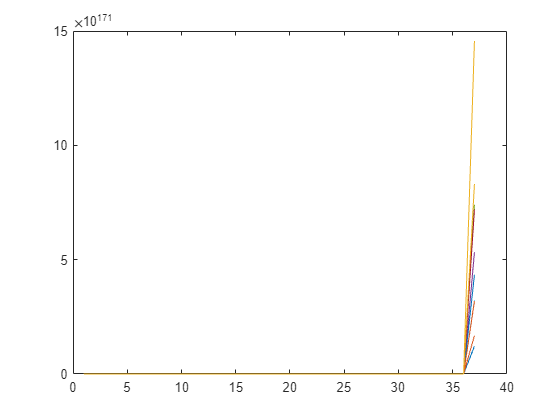

generations = 1:1:NumOfGenerations;
plot(generations, PatternPBLog);

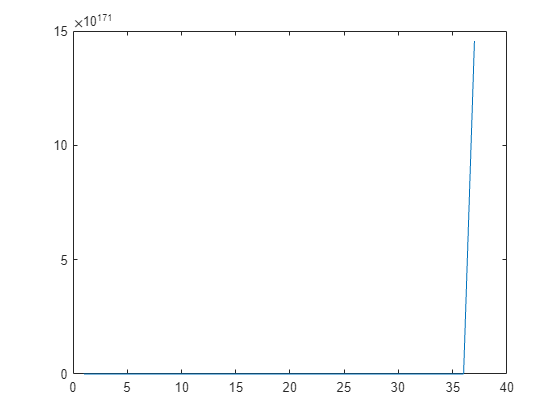

plot(generations, TeamPBLog)

TeamPB

TeamPB = Inf

figure;


%videoFileName = 'C:\Users\maxxm\OneDrive\Loughborough Year 2\Semester 2\animated_heatmap_week7.mp4';
%videoObj = VideoWriter(videoFileName, 'MPEG-4');
%videoObj.FrameRate = 20;  
%open(videoObj);
%colormap('jet');

%for i = 1:1:NumOfGenerations

%    heatmap(real(PatternXLog(:,:,gen)));
%    clim([0, 1]);
%    title(sprintf('Generation %d', i));
%    colormap jet;
%    pause(0.1);
%    frame = getframe(gcf);
%    writeVideo(videoObj, frame);
%    clf;
%end
%close(videoObj);

%disp(['The animated graph has been saved as "' videoFileName '".']);

%for pat = 1:1:NumOfPatterns
%        for ag = 1:1:PatternSize
%            PatternV(ag, pat) = c1*rand*(PatternPB(pat) - PatternX(ag,pat)) + c2*rand*(TeamPB - PatternX(ag,pat));
%            PatternM(ag, pat) = W*PatternV(ag, pat);
%            PatternX(ag, pat) = PatternX(ag, pat) + PatternV(ag, pat); + PatternM(ag, pat);
%        end
%    end

function E = ElectricField(Pattern)
    E = exp(2*pi*1i*Pattern);
end

function T = TransmissionMatrix(N, sigma)
    T = zeros(N,N);
    for i = 1:1:N
        for j = 1:1:N
            a = normrnd(0, sigma);
            b = normrnd(0, sigma);
            T(i,j) = (a + 1i*b)/N;
        end
    end
end

function T = OldTransmissionMatrix(N)
    T = zeros(N, N);
    for i = 1:N
        for j = 1:N
            a = rand() - 0.5;  
            b = rand() - 0.5;  
            T(i, j) = complex(a, b) / N;
        end
    end
end


function sigmoidMat = sigmoid(Mat)
    sigmoidMat = 1 ./ (1 + exp(-Mat));
end

function F = FindFitness(Pattern,T,CentrePixel)
    E = exp(2*pi*1i*Pattern);
    I = (abs(T*E)).^2;
    F = I(CentrePixel,:);
end
